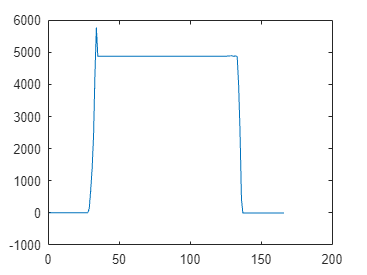

CleanData = load('Clean Data.txt');
NoisyData = load('Noisy Data.txt');
BadData = load('Bad Data.txt');

plot(CleanData)

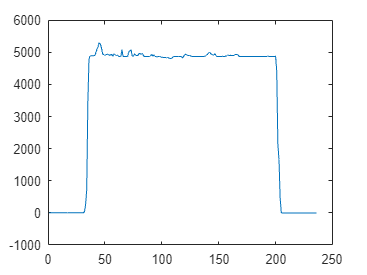

% xlabel('Samples')
% ylabel('Weight (grams)')
% title('Weight Measurements')
% xlim([0, 160])

plot(NoisyData)

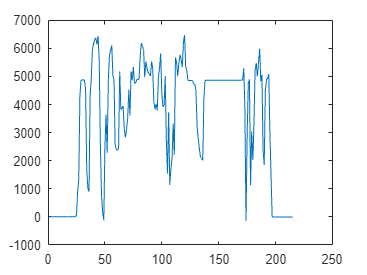

% xlabel('Samples')
% ylabel('Weight (grams)')
% title('Weight Measurements')
% xlim([0, 230])

plot(BadData)

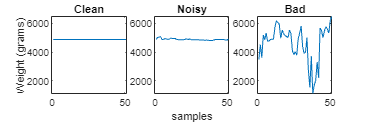

% xlabel('Samples')
% ylabel('Weight (grams)')
% title('Weight Measurements')
% xlim([0, 210])

CData = CleanData(70:120,1);

NData = NoisyData(70:120,1);

BData = BadData(70:120,1);

% Create a figure
figure('Position', [100, 100, 1800, 600]); % [left, bottom, width, height]
yLimits = [min([CData(:); NData(:); BData(:)]), max([CData(:); NData(:); BData(:)])];
% Plot medC in the first subplot
subplot(1, 3, 1);
plot(CData);
title('Clean');
ylabel("Weight (grams)")
ylim(yLimits); % Set y-axis limits
% Plot medN in the second subplot
subplot(1, 3, 2);
plot(NData);
title('Noisy');
xlabel("samples")
ylim(yLimits); % Set y-axis limits
% Plot medB in the third subplot
subplot(1, 3, 3);
plot(BData);
title('Bad');
ylim(yLimits); % Set y-axis limits


AVE = [mean(CData),mean(NData),mean(BData)]

AVE = 1.0e+03 *

    4.8800    4.8880    4.6195


ErrorRAW(1,:) = abs((AVE-4880)/4880)*100

ErrorRAW =     0.0010    0.1644    5.3379
    0.0002    0.1456    1.8221


MED = [median(CData);median(NData);median(BData)]

MED = 1.0e+03 *

    4.8800
    4.8729
    4.9689


ErrorRAW(2,:) = abs((MED-4880)/4880)*100

ErrorRAW =     0.0010    0.1644    5.3379
    0.0002    0.1456    1.8221


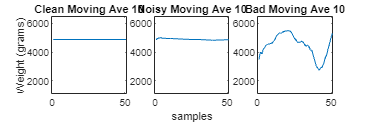


gap = 10;
alpha = 0.2;

mAveC = moveAve(CData,gap);
mAveN = moveAve(NData,gap);
mAveB = moveAve(BData,gap);
% 
% Create a figure
figure('Position', [100, 100, 1800, 600]); % [left, bottom, width, height]
% Plot medC in the first subplot
subplot(1, 3, 1);
plot(mAveC);
title('Clean Moving Ave 10');
ylabel("Weight (grams)")
ylim(yLimits); % Set y-axis limits
% Plot medN in the second subplot
subplot(1, 3, 2);
plot(mAveN);
title('Noisy Moving Ave 10');
xlabel("samples")
ylim(yLimits); % Set y-axis limits
% Plot medB in the third subplot
subplot(1, 3, 3);
plot(mAveB);
title('Bad Moving Ave 10');
ylim(yLimits); % Set y-axis limits


MEDMa = [median(mAveC);median(mAveN);median(mAveB)]

MEDMa = 1.0e+03 *

    4.8800
    4.8854
    4.5955


ErrorF(1,:) = abs((MEDMa-4880)/4880)*100

ErrorF =     0.0007    0.1116    5.8296
    0.0008    0.1111    5.4456
    0.0010    0.1644    5.3379


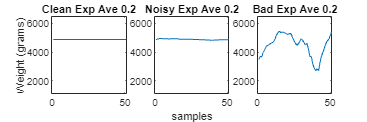


eAveC = EMA(CData, alpha);
eAveN = EMA(NData, alpha);
eAveB = EMA(BData, alpha);

% Create a figure
figure('Position', [100, 100, 1800, 600]); % [left, bottom, width, height]
% Plot medC in the first subplot
subplot(1, 3, 1);
plot(eAveC);
title('Clean Exp Ave 0.2');
ylabel("Weight (grams)")
ylim(yLimits); % Set y-axis limits
% Plot medN in the second subplot
subplot(1, 3, 2);
plot(eAveN);
title('Noisy Exp Ave 0.2');
xlabel("samples")
ylim(yLimits); % Set y-axis limits
% Plot medB in the third subplot
subplot(1, 3, 3);
plot(eAveB);
title('Bad Exp Ave 0.2');
ylim(yLimits); % Set y-axis limits


MEDE = [median(eAveC);median(eAveN);median(eAveB)]

MEDE = 1.0e+03 *

    4.8800
    4.8854
    4.6143


ErrorF(2,:) = abs((MEDE-4880)/4880)*100

ErrorF =     0.0007    0.1116    5.8296
    0.0008    0.1111    5.4456
    0.0010    0.1644    5.3379


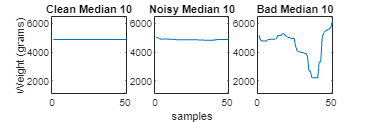


medC = medfil(CData, gap);
medN = medfil(NData, gap);
medB = medfil(BData, gap);

% Create a figure
figure('Position', [100, 100, 1800, 600]); % [left, bottom, width, height]
% Plot medC in the first subplot
subplot(1, 3, 1);
plot(medC);
title('Clean Median 10');
ylabel("Weight (grams)")
ylim(yLimits); % Set y-axis limits
% Plot medN in the second subplot
subplot(1, 3, 2);
plot(medN);
title('Noisy Median 10');
xlabel("samples")
ylim(yLimits); % Set y-axis limits
% Plot medB in the third subplot
subplot(1, 3, 3);
plot(medB);
title('Bad Median 10');
ylim(yLimits); % Set y-axis limits


MEDM = [median(medC);median(medN);median(medB)]

MEDM = 1.0e+03 *

    4.8799
    4.8793
    4.4765


ErrorF(3,:)  = abs((AVE-4880)/4880)*100

ErrorF =     0.0007    0.1116    5.8296
    0.0008    0.1111    5.4456
    0.0010    0.1644    5.3379


function mAve = moveAve(data, gap)

    mAve = zeros(1, length(data));

    for i = 1:length(data)

        start_gap = max(1, i - gap + 1);
        end_gap = min(length(data), i);
        
        gap_sum = sum(data(start_gap:end_gap));
        
        mAve(i) = gap_sum / (end_gap - start_gap + 1);
    end
end

function filtered_data = medfil(data, gap)

    filtered_data = zeros(size(data));

    for i = 1:length(data)

        start_idx = max(1, i - floor(gap / 2));
        end_idx = min(length(data), i + floor(gap / 2));

        window_elements = data(start_idx:end_idx);

        sorted_window = sort(window_elements);

        if mod(gap, 2) == 0
            median_val = (sorted_window(floor(gap / 2)) + sorted_window(ceil(gap / 2))) / 2;
        else
            median_val = sorted_window(ceil(gap / 2));
        end

        filtered_data(i) = median_val;
    end
end

function ema = EMA(data, alpha)

    ema = zeros(size(data));
    ema(1) = data(1);

    for i = 2:length(data)
        ema(i) = alpha * data(i) + (1 - alpha) * ema(i - 1);
    end
end